# **Amar Ramdas - 4461487**

## **Exercise 1:**

P7.1. Write a program that illustrates the timescale invariance of the asset model, in the style of Figure 7.5

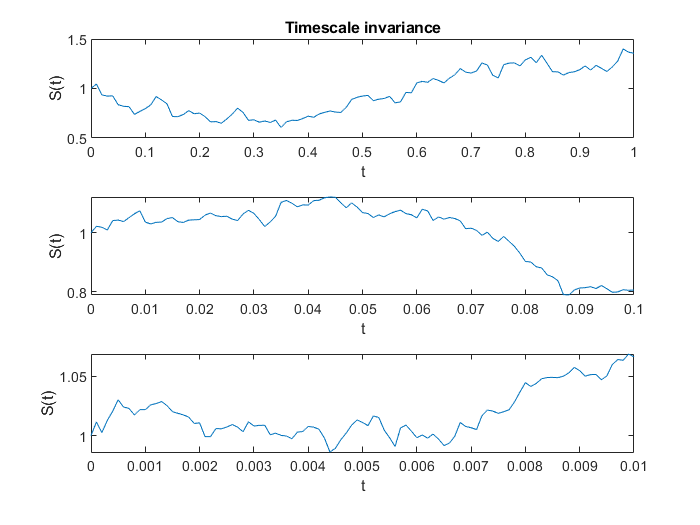

%CH07 Program for Chapter 7 % % Plot discrete sample paths
clear all;
randn('state',100) ;
clf

%%%%%%%%% Problem parameters %%%%%%%%%%
S=1; mu=0.05; sigma = 0.5; L = 1e2; 

for i = 0:2
    T = 10^-i; 
    dt =T/L; M = 1; 

    tvals = [0:dt:T]; 
    Svals = S*cumprod(exp((mu-0.5*sigma^2)*dt + sigma*sqrt(dt)*randn(M,L)),2); 
    Svals = [S*ones(M,1) Svals]; % add initial asset price 
    
    
    h(i+1) = subplot(3,1,i+1);
        
    plot(tvals,Svals)
    xlabel('t'), ylabel('S(t)')
    
    if i==0
            title('Timescale invariance') 
    end
end 

**Exercise 2:**

Solve Exercise 8.10 from the book by Higham, page 83

%function [C, Cdelta, P, Pdelta] = ch08(S,E,r,sigma,tau) % Program for Chapter 8 % This is a MATLAB function % % Input arguments: S = asset price at time t % E=Exercise price % r=interest rate % sigma = volatility % tau = time to expiry (T-t) % % Output arguments: C = call value, Cdelta = delta value of call % P=Put value, Pdelta = delta value of put % % function [C, Cdelta, P, Pdelta] = ch08(S,E,r,sigma,tau)


**Exercise 3:**

a) generate 10 asset paths driven by geometric Brownian motion and the parameters above

studentno = 4461487;
mu = studentno;

%divide mu by 10 until mu<0.1
while mu>0.1
mu = mu / 10;
end

mu

mu = 0.0446

sigma = mu*4

sigma = 0.1785

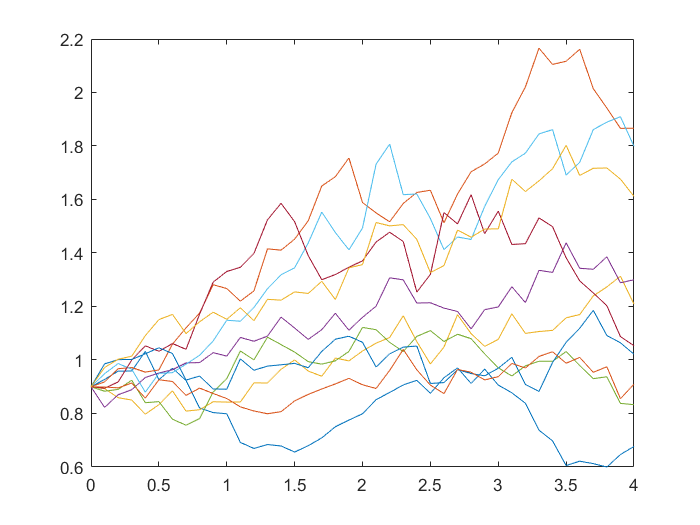

s0 = 0.9;

T=4;
dt= 10^-1;

steps = T/dt;

%using matlab geometric Brownian Motion function
obj = gbm(mu, diag(sigma), 'StartState', s0) ;
[X1,T] = obj.simulate(steps, 'DeltaTime', dt,'ntrials', 10);
X1 = squeeze(X1);
figure()
plot(T,X1)
xlim([0, 4])

b)   Plot for these paths the "running sum of square returns". Repeat this exercise with 1000 asset paths